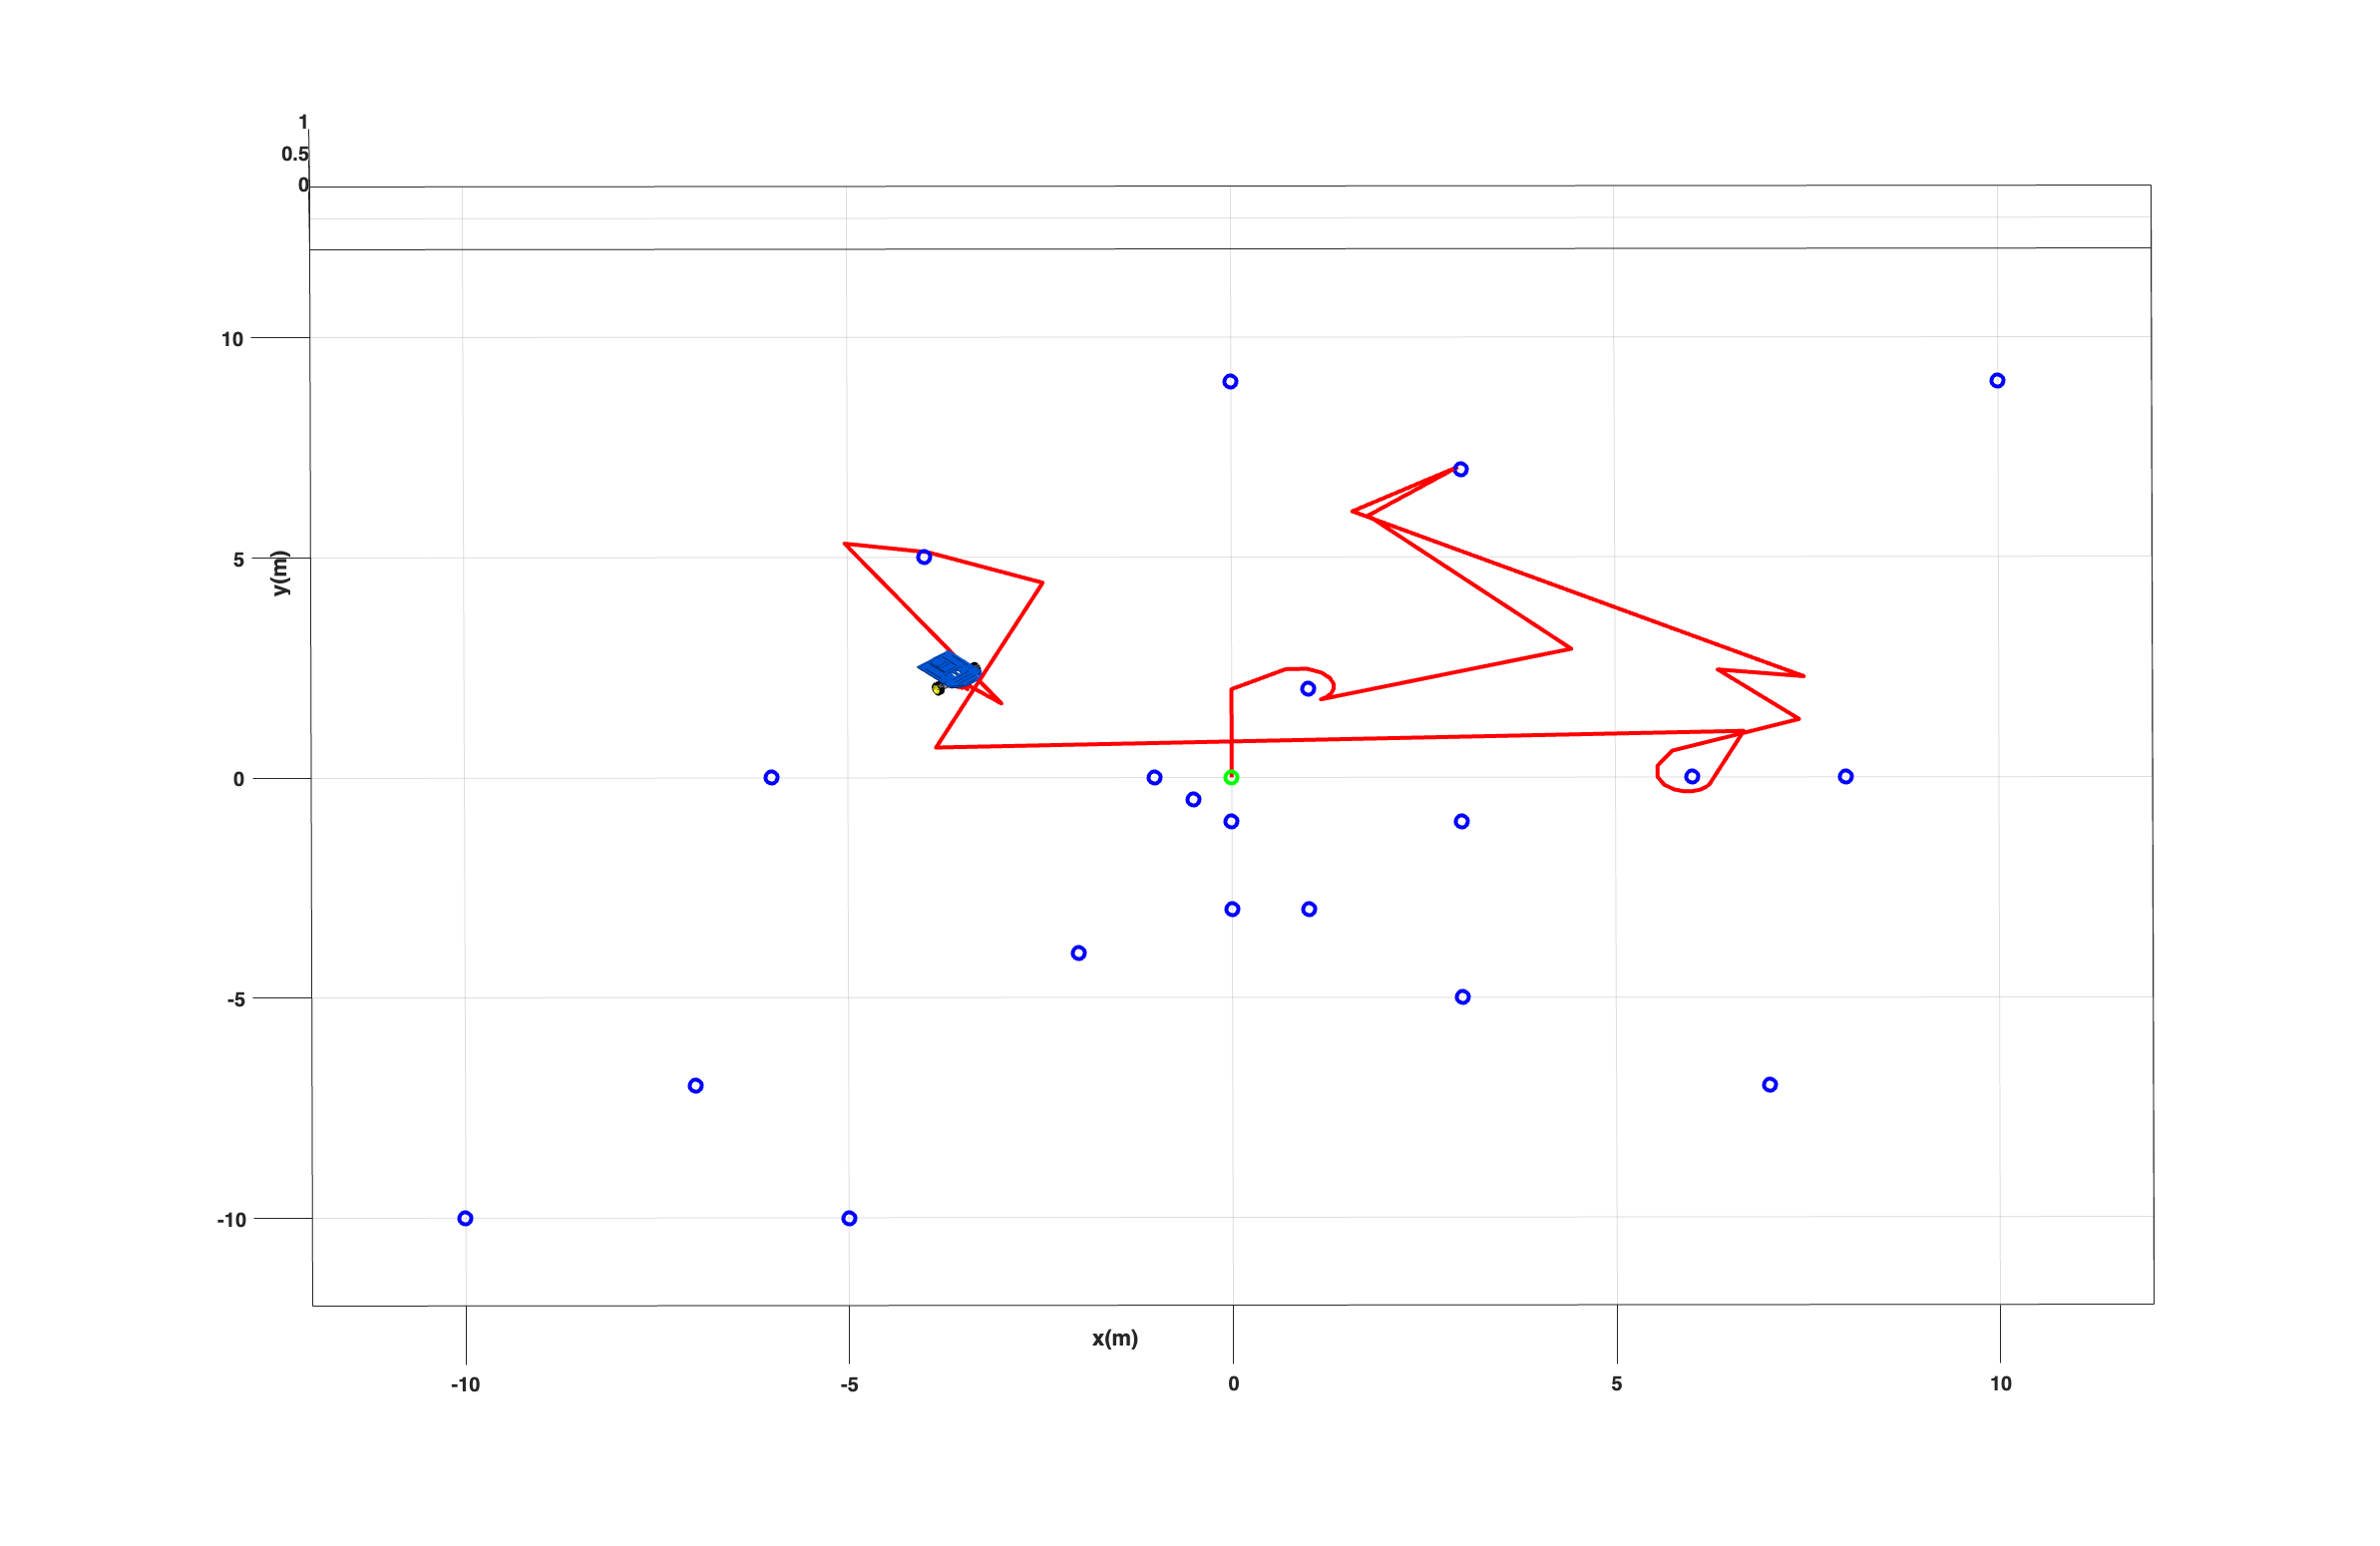

%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=100;             % Tiempo de simulación en segundos (s)
ts=0.1;             % Tiempo de muestreo en segundos (s)
t=0:ts:tf;          % Vector de tiempo
N= length(t);       % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=pi/2; %Orientación inicial del robot 

%3 POSICION DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
puntos = [1 2; 3 7; 6 0; -4 5; -6 0; -1 0; -7 -7; -2 -4; -0.5 -0.5;
          1 -3; 3 -5; 8 0; 0 -3; 0 9; 0 -1; -5 -10; 7 -7; 3 -1; -10 -10; 10 9];

target_idx = 1;
hxd = puntos(target_idx,1);
hyd = puntos(target_idx,2);
error_threshold = 0.3;

hx(1)= x1(1);       
hy(1)= y1(1);       

%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
K = [10 0; 0 10];  % MATRIZ DE GANANCIA USADA PARA SIMULACIÓN VISUAL ORIGINAL

for k=1:N 
    hxe(k)=hxd-hx(k);
    hye(k)=hyd-hy(k);
    he= [hxe(k);hye(k)];
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    if Error(k) < error_threshold && target_idx < size(puntos,1)
        target_idx = target_idx + 1;
        hxd = puntos(target_idx,1);
        hyd = puntos(target_idx,2);
    end

    if target_idx == size(puntos,1) && Error(k) < error_threshold
        N = k;
        break;
    end

    J=[cos(phi(k)) -sin(phi(k));
       sin(phi(k)) cos(phi(k))];

    qpRef= pinv(J)*K*he;

    v(k)= qpRef(1);   
    w(k)= qpRef(2);   

    phi(k+1)=phi(k)+w(k)*ts;           
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
    x1(k+1)=x1(k)+ xp1*ts;
    y1(k+1)=y1(k)+ yp1*ts;
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold') ;
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight'); 
axis equal; 
grid on; 
box on; 
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]); 
axis([-12 12 -12 12 0 1]); 

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(puntos(:,1),puntos(:,2),zeros(size(puntos,1),1),'bo','lineWidth',2);
H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);

step=1;
for k=1:step:N
    delete(H1);    
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;
set(graph,'position',sizeScreen);
subplot(311)
plot(t(1:N),v(1:N),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w(1:N),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error(1:N),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% COMPARACIÓN CON 3 GANANCIAS DIFERENTES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
K1 = [2 0; 0 2];
K2 = [10 0; 0 10];
K3 = [25 0; 0 25];

[t1, v1, w1, E1] = simularRobotGanancia(K1, ts, tf, puntos);
[t2, v2, w2, E2] = simularRobotGanancia(K2, ts, tf, puntos);
[t3, v3, w3, E3] = simularRobotGanancia(K3, ts, tf, puntos);

figure('Name','Comparación de respuestas con diferentes ganancias','Position',get(0,'ScreenSize'));

subplot(3,1,1)
plot(t1,v1,'r','LineWidth',2); hold on
plot(t2,v2,'g','LineWidth',2);
plot(t3,v3,'b','LineWidth',2);
grid on; ylabel('v (m/s)'); title('Velocidad Lineal');
legend('K=2','K=10','K=25');

subplot(3,1,2)
plot(t1,w1,'r','LineWidth',2); hold on
plot(t2,w2,'g','LineWidth',2);
plot(t3,w3,'b','LineWidth',2);
grid on; ylabel('w (rad/s)'); title('Velocidad Angular');
legend('K=2','K=10','K=25');

subplot(3,1,3)
plot(t1,E1,'r','LineWidth',2); hold on
plot(t2,E2,'g','LineWidth',2);
plot(t3,E3,'b','LineWidth',2);
grid on; xlabel('Tiempo (s)'); ylabel('Error (m)'); title('Error de Posición');
legend('K=2','K=10','K=25');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% FUNCION DE SIMULACION PARA COMPARACIÓN DE GANANCIAS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [t, v, w, Error] = simularRobotGanancia(K, ts, tf, puntos)
    t = 0:ts:tf;
    N = length(t);
    x1(1)=0; y1(1)=0; phi(1)=pi/2;
    hx(1)=x1(1); hy(1)=y1(1);
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);
    idx = 1; hxd = puntos(idx,1); hyd = puntos(idx,2);
    error_threshold = 0.3;

    for k=1:N
        hxe = hxd - hx(k);
        hye = hyd - hy(k);
        he = [hxe; hye];
        Error(k) = norm(he);

        if Error(k) < error_threshold && idx < size(puntos,1)
            idx = idx + 1;
            hxd = puntos(idx,1);
            hyd = puntos(idx,2);
        end

        if idx == size(puntos,1) && Error(k) < error_threshold
            t = t(1:k); v = v(1:k); w = w(1:k); Error = Error(1:k);
            break;
        end

        J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];
        qpRef = pinv(J)*K*he;
        v(k) = qpRef(1); w(k) = qpRef(2);
        phi(k+1) = phi(k) + w(k)*ts;
        x1(k+1) = x1(k) + v(k)*cos(phi(k))*ts;
        y1(k+1) = y1(k) + v(k)*sin(phi(k))*ts;
        hx(k+1) = x1(k+1); hy(k+1) = y1(k+1);
    end
end
